# Torque in a Variable Reluctance Machine

In this section, analytical solution of torque in a variable reluctance machine shown in figure below.

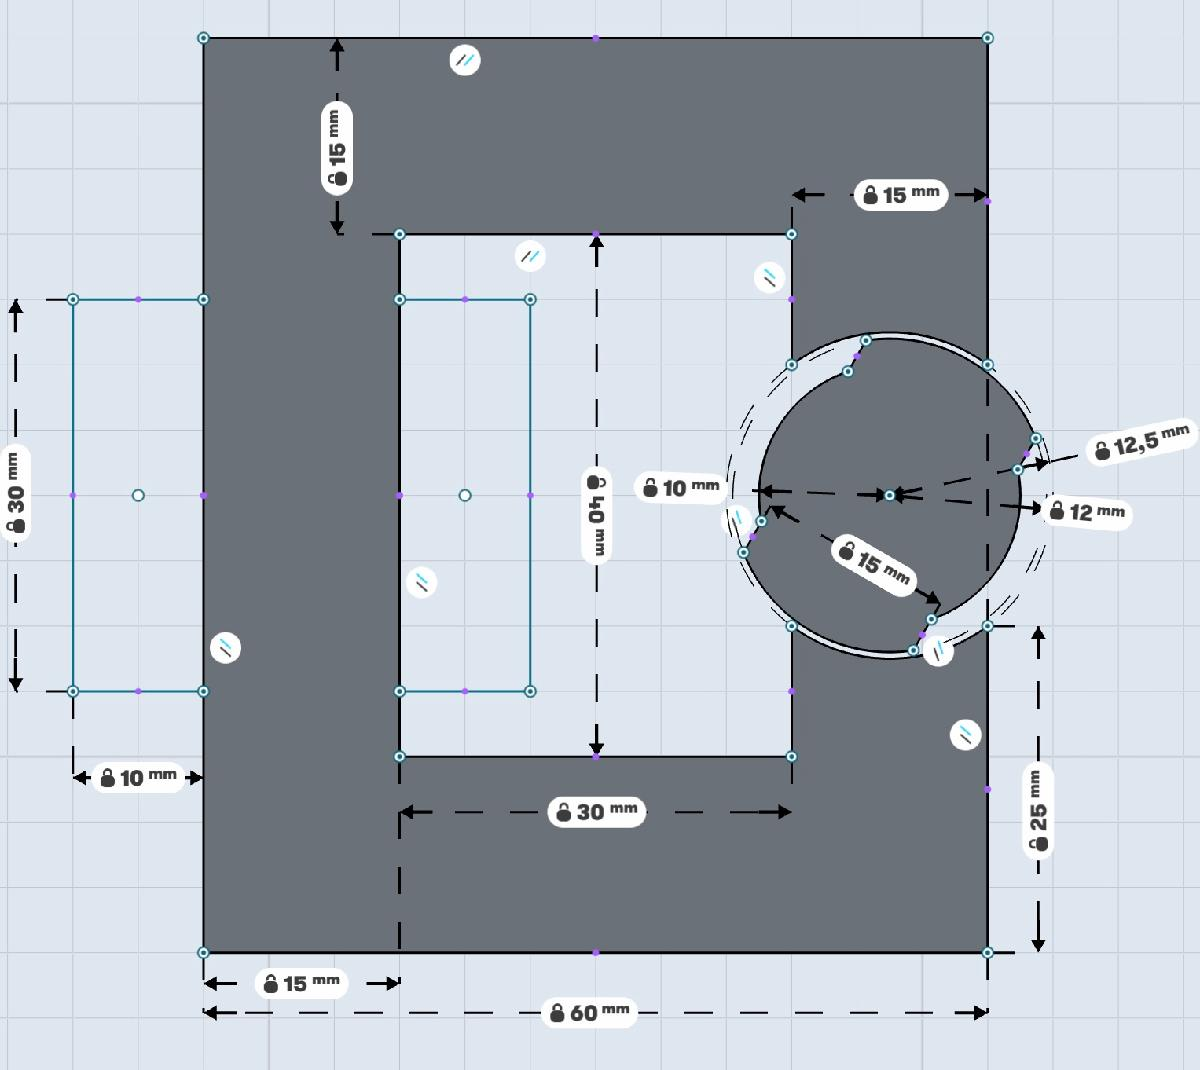

the machine rotor is ferromagnetic material and there is no external winding or magnets on rotor. The torque is produced by reluctance.Thus, torque is related by relcutance change. If we can calculate reluctance for each position of rotor, torque can be calculated. 


$$T_e =\frac{1}{2}{\mathrm{Li}}^{2\;} =\frac{1}{2\;}\frac{N^{2\;} }{R}i^{2\;\;}$$


position =linspace(0,180,180); %% Reluctance is periodic of 2 times of mechanical angle. 
%% rotor airgap distrbution
airgap_d=0.5e-3; %m it is only valid for zero angle
airgap_q= 2.5e-3; %m it is only valid for 90 degree
airgap_pass=1.5e-3;
% d axis is in range of 77 
% airgap_pass is 3degree
% q axis is in range of  97 degree
d_len=77;
pass_len=3;
q_len=97;
average_airgap= zeros(1,180);

for i=1:length(position)
    
    if position(i) < d_len && position(i) < 3
        average_airgap(i)= (d_len-position(i))*airgap_d+ position(i)*airgap_pass;
        disp(1);
    end
    
    if position(i) < d_len && position(i) > 3
         average_airgap(i)= (d_len-position(i))*airgap_d+ (pass_len)*airgap_pass+ (position(i)-pass_len)*airgap_q;   
         disp(2);
         
    end
    
    if  position(i) > d_len && position(i) < d_len+pass_len
             average_airgap(i)= (d_len+pass_len-position(i))*airgap_pass+ (position(i)-pass_len)*airgap_q ;
         disp(3);
         
    end
    
    if  position(i) > d_len+pass_len && position(i) < 180-pass_len
             average_airgap(i)= d_len*airgap_q;
             disp(4);
    end
%           average_airgap(i)= d_len*airgap_q;
%            disp(5);
%     end
%     
    
average_airgap=average_airgap/d_len;
    
end

     1

     1

     1



     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2

     2



     3

     3

     3



     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4

     4



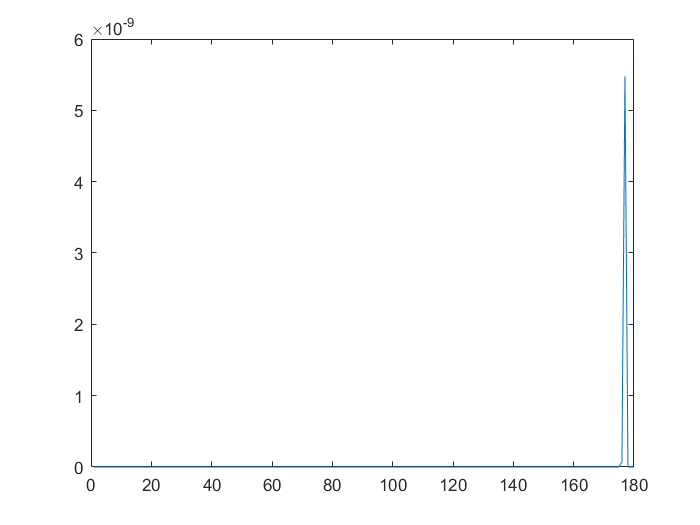


plot(average_airgap)